# Spatial Revenue Density Analysis for Capoeira Studio Franchises

This project builds a MATLAB-based analytical tool to simulate, analyze, and visualize revenue efficiency across a Capoeira studio. The goal is to calculate Revenue per Square Foot (Revenue Density) and identify which class types generate the highest financial return relative to space usage.

To achieve this, synthetic data was generated to simulate 12 months of studio activity, including attendance patterns across four class types: Roda, Beginner, Intermediate, and Music. The data incorporates seasonal trends  and random variations to reflect realistic fluctuations. Each class type is associated with a pricing structure and a defined space requirement, allowing for the calculation of total revenue and revenue density.

Visualization techniques such as heatmaps and contour plots were used to represent how revenue is distributed across the studio layout, while trend anlaysis was applied to examine attendance and revenue patterns over time.This approach provides a comprehensive framework for understanding both operational performance and spatial efficiency within the studio environment.

clc;clear; close all;
rng(1);

% Synthetic data generation
months = 1:12;
numMonths = length(months);

% class types
classTypes = {'Roda','Beginner','Intermediate','Music'};
numClasses = length(classTypes);

% Membership tiers (Cordao levels)
tiers = {'Beginner','Intermediate','Advanced'};

% price per class
price = [15, 10, 12, 8];

% space requirements (sq ft)
space = [800, 500, 600, 300];

%generating synthetic attendance data
attendance = zeros(numMonths,numClasses);

for i = 1:numClasses
    base = randi([20,50]); % average attendance for that class
    seasonal = 10*sin((1:numMonths)*pi/6); % real life has busy / slow season
    noise = randi([-5,5],1,numMonths); % random fluctuations
    attendance(:,i) = base + seasonal' + noise';

end

attendance = max(attendance, 5); % ensures no negative values

% generate membership distribution

beginner_pct = 0.5;
intermediate_pct = 0.3;
advanced_pct = 0.2;


%calculate Revenue

revenue = zeros(numMonths, numClasses);

for i = 1:numClasses
    revenue(:,i) = attendance(:,i) * price(i); 
end

%total attendance across all classes per month
totalAttendance = sum(attendance, 2);

%total revenue across all classes per month
totalRevenue = zeros(length(months),1);

for i = 1:length(price)
    totalRevenue = totalRevenue + attendance(:,i) * price(i);
end

%Revenue contribution by tier

rev_beginner = totalRevenue * beginner_pct;
rev_intermediate = totalRevenue * intermediate_pct;
rev_advanced = totalRevenue * advanced_pct;

% storing in table

dataTable = array2table(attendance, 'VariableNames', classTypes);
disp(dataTable);

    Roda     Beginner    Intermediate    Music
    _____    ________    ____________    _____

       39        47            22           53
    35.66     57.66         26.66        54.66
       40        56            36           51
    36.66     56.66         26.66        54.66
       33        48            26           44
       29        44            27           42
       25        45            17           42
    22.34     43.34         15.34        32.34
       22        35            10           31
    22.34     40.34         15.34        30.34
       29        46            21           33
       29        51            17           45



## Spatial Revenue Mapping

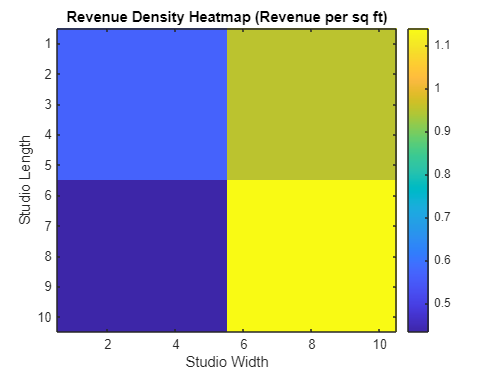

% Revenue Density calculation

revenueDensity = zeros(numMonths,numClasses);

for i = 1:numClasses
    revenueDensity(:,i) = revenue(:,i) ./ space(i);
end

%create spatial grid (studio layout simulation)

gridSize = [10,10];
spatialMap = zeros(gridSize);

%Assign zones manually
spatialMap(1:5, 1:5) = mean(revenueDensity(:,1));  %Roda
spatialMap(1:5, 6:10) = mean(revenueDensity(:,2));  %Beginner
spatialMap(6:10, 1:5) = mean(revenueDensity(:,3));  %Intermediate
spatialMap(6:10, 6:10) = mean(revenueDensity(:,4)); %Music

% Heatmap Visualization
figure
imagesc(spatialMap);
colormap(parula);
colorbar;
title("Revenue Density Heatmap (Revenue per sq ft)");
xlabel("Studio Width");
ylabel("Studio Length");

This heatmap represents the physical floor plan of the studio. The hotter colors identify zones where classes generate the most money relative to their size.

It allows the final analyst to see  if a small "Music" room is actually more profitable per square foot than a massive "Roda" area. If the large space is not generating a hot color the studio is technically wasting space. Higher number (1.4) more money per space.Music is the most efficient class with yellow color(peak). Music classes generate the highest revenue per square foot despite having the lowest attendance, it uses little space (300 sq ft).

Beginner class is second best (0.95). beginner class provide a strong balance between attendance and space. good for scaling business and stable income.

## Contour **Plot of Revenue**

while the heatmap is blocky, this contour plot uses gradient lines to show how revenue density flows across the facility. It helps to identify thresholds. it can clearly outline the exact areas where revenue drops below a certain profitable level.

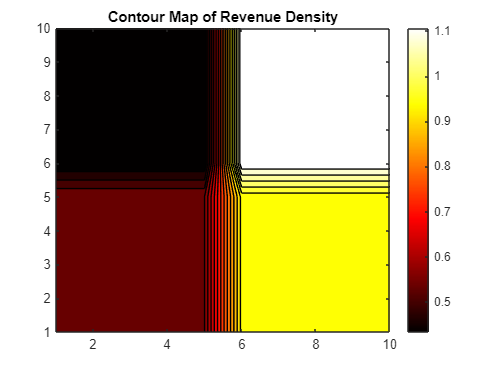

%% Counter 
figure;
contourf(spatialMap,20);
colorbar;
title('Contour Map of Revenue Density');
colormap("hot");

## Trend  Visualization

specifically for  seasonal attendance. it shows 12 months of synthetic data along the X-axis. This helps to see when the studio is most crowded.

seasonal trends affect revenue: attendance fluctuates, revenue follows similar pattern. This helps with Scheduling, Staffing and promotion.

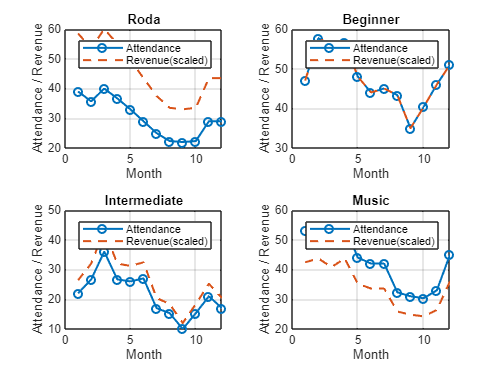

%trend visualization
figure;
tiledlayout(2,2);
for i = 1:numClasses
    nexttile;
    plot(months, attendance(:,i), '-o', 'LineWidth',1.5);
    hold on;
    plot(months, revenue(:,i)/10, '--','LineWidth',1.5); %scaled revenue
    title(classTypes{i});
    xlabel('Month');
    ylabel('Attendance / Revenue');
    legend('Attendance','Revenue(scaled)');
    grid on;
end

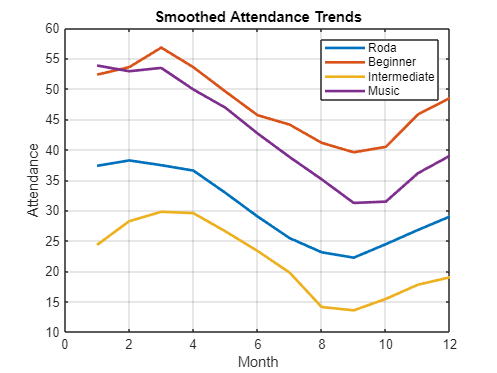


% Data smoothing(Moving average)
smoothedAttendance = movmean(attendance,3);
figure;
plot(months, smoothedAttendance, 'LineWidth',2);
title('Smoothed Attendance Trends');
xlabel('Month');
ylabel('Attendance');
legend(classTypes);
grid on;

%%Export to PDF
exportgraphics(gcf, 'Capoeira_Report.pdf','Resolution',300);

The analysis reveals that Beginner classes consistently achieve  the highest attendance, making them the most popular offering. Music classes also demonstrate strong participation.However, Roda and intermediate classes have lower attendance. So, with high space in roda and intermediate classes having lower attendance means lower revenue, so it is not profitable.

Seasonal trends are evident, with peak attendance classes drive total revenue, smaller classes may offer better revenue efficiency when evaluated per square foot, highlighting opportunities for optimizing studio space allocation. It helps to consider the specific seasons when attendance or revenue fluctuates and put solution for it.

## Comparison of membership distribution

To address the requirement of analyzing revenue by student experience levels attendance data was proportionally divided into Beginner, Intermediate, and Advanced Cordao tiers. The analysis shows that beginner-level students contribute the largest share of total revenue due to theier higher population percentage. Advanced students, while fewer in mumber represents a stable and committed segment. Revenue trends across tiers follow similar seasonal patterns, indicating that overall attendance strongly influences income. This highlights the importance of maintaining a steady intake of new students while also improving retention to increase adavanced level participation  

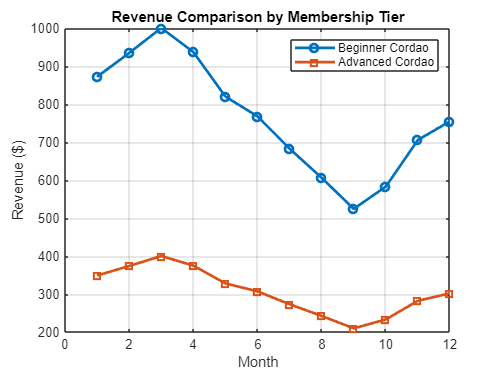

%plot comparison of membership distribution
figure;
plot(months, rev_beginner, '-o','LineWidth',2);
hold on;
plot(months, rev_advanced, '-s','LineWidth',2);

title('Revenue Comparison by Membership Tier');
xlabel('Month');
ylabel('Revenue ($)');
legend('Beginner Cordao','Advanced Cordao');
grid on;

Beginner Cordao students contribute the largest share of total revenue due to their higher population percentage. Even if they pay less, there are more of them.

Advanced Cordao students generate a smaller portion of revenue due to lower representation, despite potentially higher engagement.The studio relies heavily on beginner -level students for revenue generation.

## Conclusion

The analysis demonstrates that class performance can not be evaluated based on attendance alone, as spatial efficiency plays a critical role in overall profitability. While Beginner and Music classes show the highest attendance levels, Music classes emerge as the most efficient due to their low space requirements and strong participation, resulting in the highest revenue per square foot.

In contrast Roda and Intermediate classes require larger areas, which reduces their revenue efficiency despite moderate attendance levels. This indicates that large, high capacity classes do not always provide the best return on space utilization. The heatmap visualization clearly highlights these differences, allowing for easy identification of high performing and underutilized zones with in the studio.

Additionally the trend analysis reveals seasonal fluctuations in attendance and revenue, which can be used to optimize scheduling, staffing, and promotional strategies. Overall, the findings emphasize the importance of balancing class popularity with spatial optimization. By prioritizing high-efficiency classes and improving underperforming ones, studio management can enhance both profitability and operational effectiveness.